# Tarea 2

**De la especificaciones de diseño dadas archivo adjunto (sobrepaso, tiempo de establecimiento 2 % y error de régimen ante escalón=0)**

%% Calculo de parametros 2do orden
% Especificaciones de diseño
S = 15;
ts = 4;
e = 0;
Tm=0.19;

psita = -log(S/100)/sqrt(pi^2+log(S/100)^2)

psita = 0.5169

wo = 4/(psita*ts)

wo = 1.9345

wd = wo*sqrt(1-psita^2)

wd = 1.6560

td = 2*pi/wd

td = 3.7942

m = round(td/Tm);

r = exp(-psita*wo*Tm)

r = 0.8270

Omega = wd*Tm

Omega = 0.3146


[x y] = pol2cart(Omega,r);
z1 = x+j*y

z1 = 0.7864 + 0.2559i

z2 = x-j*y

z2 = 0.7864 - 0.2559i


c = -10;
p1 = -3;
p2 = 0;
K = 10;

G=zpk(-10,[-3 0],10)


G =
 
  10 (s+10)
  ---------
   s (s+3)
 
Continuous-time zero/pole/gain model.



Gd=c2d(G,Tm,'zoh')


Gd =
 
  2.9541 (z-0.06852)
  ------------------
   (z-1) (z-0.5655)
 
Sample time: 0.19 seconds
Discrete-time zero/pole/gain model.




%sisotool(Gd);

## Diseño de un controlador PI

Se diseña con *sisotool* un controlador PI para los parámetros de diseño. 

load("pi_out.mat");
C


C =
 
  0.059419 (z-0.8793)
  -------------------
         (z-1)
 
Name: C
Sample time: 0.19 seconds
Discrete-time zero/pole/gain model.



Simulando el controlador obtenido

F=feedback(C*Gd,1) % sistema de lazo cerrado


F =
 
    0.17553 (z-0.8793) (z-0.06852)
  ----------------------------------
  (z-0.8132) (z^2 - 1.577z + 0.6825)
 
Sample time: 0.19 seconds
Discrete-time zero/pole/gain model.



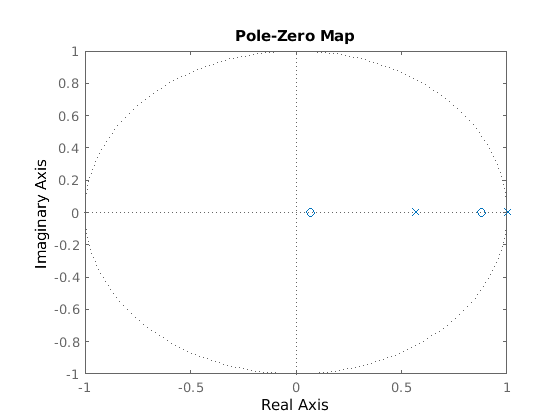

pzmap(C*Gd)

pole(F)

ans =    0.7884 + 0.2467i
   0.7884 - 0.2467i
   0.8132 + 0.0000i


zero(F)

ans =     0.8793
    0.0685


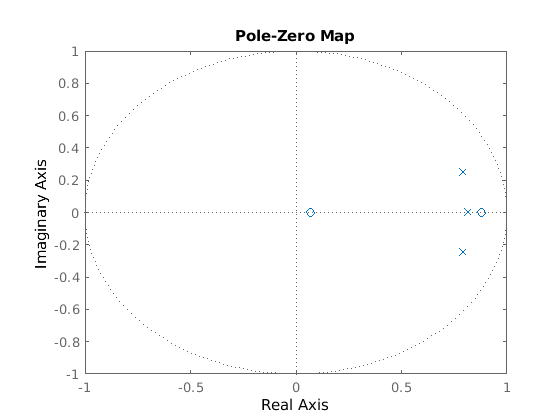

pzmap(F)

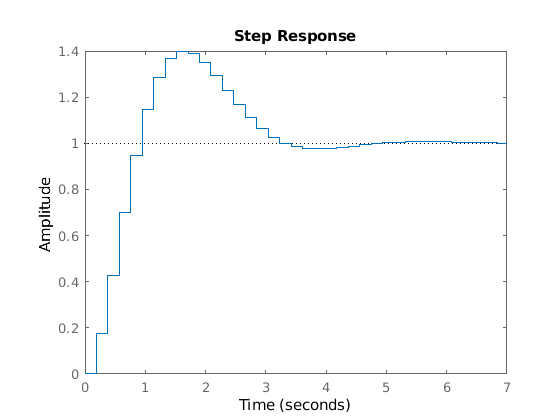

step(F) % respuesta al escalon

stepinfo(F)

ans = struct with fields:
        RiseTime: 0.5700
    SettlingTime: 4.1800
     SettlingMin: 0.9465
     SettlingMax: 1.3993
       Overshoot: 39.9290
      Undershoot: 0
            Peak: 1.3993
        PeakTime: 1.5200


Se puede observar que a partir del diseño realizado, no se cumple el sobrepaso requerido. Si cancelamos el polo de la planta con el cero del controlador PI, no se pueden cumplir las especificaciones de diseño a partir de un cambio de ganancia del controlador.

## Diseño de un controlador PD

Puesto que el sistema posee un integrador puro, su error en estado estable para una entrada escalón será nulo (sistema tipo 1). Se decide diseñar un control PD para mejorar su respuesta transitoria.

%sisotool(Gd)
load('pd_out.mat')
F=feedback(C*Gd,1) % sistema de lazo cerrado


F =
 
   0.18572 (z-0.5655) (z-0.06852)
  ---------------------------------
  (z+0.01534) (z-0.5655) (z-0.8296)
 
Sample time: 0.19 seconds
Discrete-time zero/pole/gain model.



pole(F)

ans =    -0.0153
    0.8296
    0.5655


zero(F)

ans =     0.5655
    0.0685


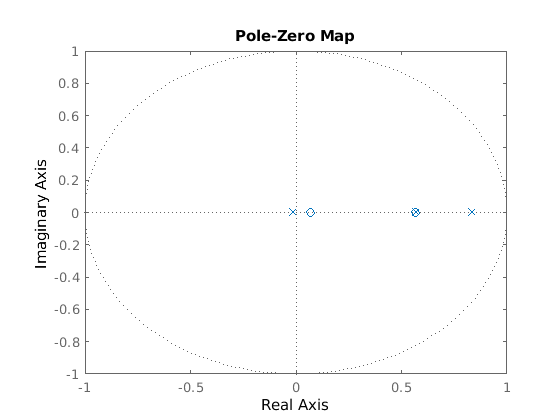

pzmap(F)

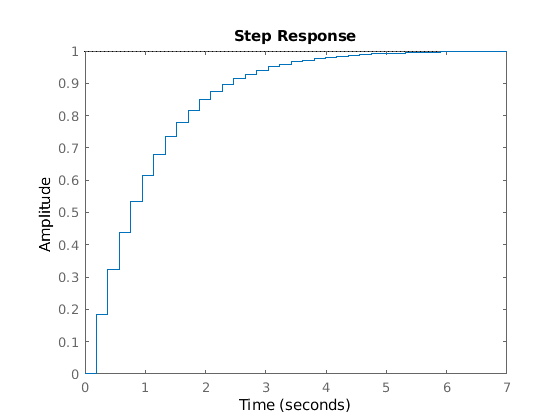

step(F) % respuesta al escalon

stepinfo(F)

ans = struct with fields:
        RiseTime: 2.2800
    SettlingTime: 3.9900
     SettlingMin: 0.9134
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 15.0100


Se puede observar que a partir del diseño del controlador PD se cumplen las especificaciones de diseño y además se obtiene sobrepaso nulo.

## Simulacion del PD mediante SIMULINK

Para simular el controlador PD, se deben de calcular los parámetros del controlador KD y KP.

%parametros PID
syms kp kd ki k c b 
eq1 = kp + kd == k

$$eq1 = \mathrm{kd}+\mathrm{kp}=k$$

eq2 = kd/(kp+kd) == b

$$eq2 = \frac{\mathrm{kd}}{\mathrm{kd}+\mathrm{kp}}=b$$

S1=solve(eq1,eq2,kp,kd);

c_o = zero(C);
b = c_o(1);
c = 0;
k = C.K;

kp = k - b*k

kp = 0.0273

kd = b*k

kd = 0.0356

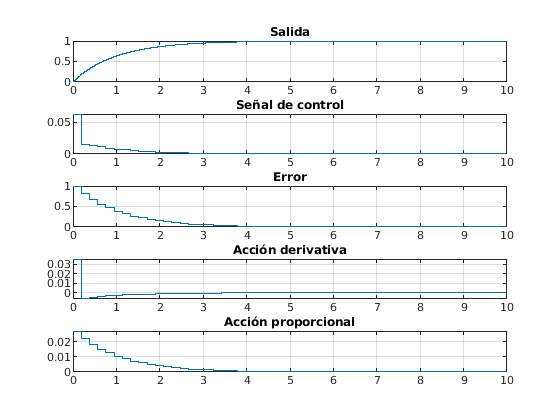

ki= 0;
T = Tm;
sim('PID_digital_tarea.slx')


subplot(5,1,1);
plot(tout,yout(:,1)) 
grid on
title('Salida')
subplot(5,1,2);
plot(tout,yout(:,2)) 
grid on
title('Señal de control')
subplot(5,1,3);
plot(tout,yout(:,3)) 
grid on
title('Error')
subplot(5,1,4);
plot(tout,yout(:,4)) % salida del sistema
grid on
title('Acción derivativa')
subplot(5,1,5);
plot(tout,yout(:,6)) % salida del sistema
grid on
title('Acción proporcional')